# **SS - lab S7 - Zeic Beniamin**

**Exercise 2**

a) After running the simulation for different time samples, I could see that for significantly larger time sample periods, the functions were plotted very coarse.

b) After adding more coefficients of the Fourier series, the Fourier signal gets closer to the original one, but the spikes on the edges of the signal increase in height.

c) Plot each of the x_est signal components and their partial sums. (Solved below "Example3 - Signal synthesis")

**Example 2 - Fourier coefficient estimation**

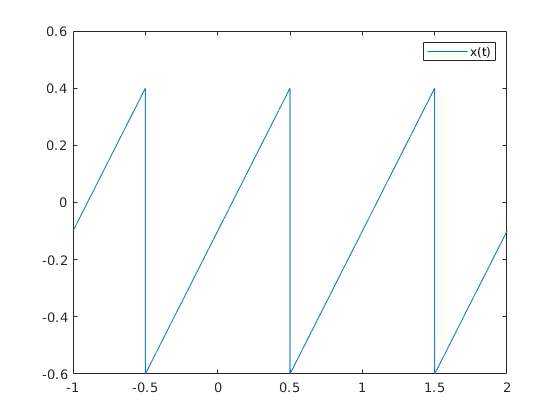

% Generate the input signal, x:
% T0 - fundamental period
T0 = 1;
% w0 - fundamental angular frequency
w0 = 2*pi/T0;
% Ts - sampling period
Ts = 0.0001;
% t - linear space with granularity Ts
t = -1:Ts:2;

% round(t) used as a step function
x = t - 0.1 - round(t);

figure
plot(t,x)
legend('x(t)');


N = 8;
ak = fsAnalysis(x, t, T0, Ts, N);

**Example 3 - Signal synthesis**

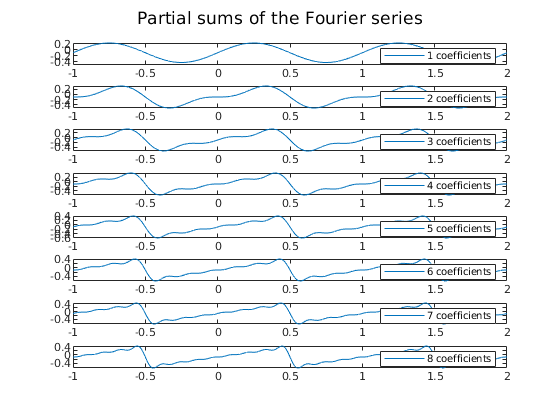

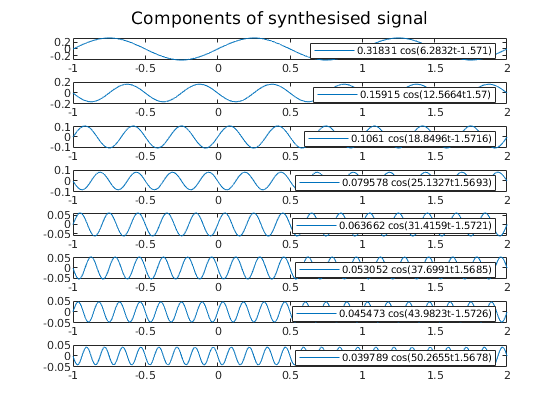

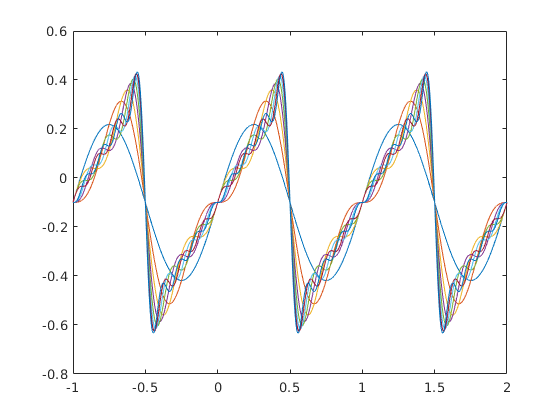

% Take the coefficient a0
a0 = ak(N+1);
ksi0 = 0;
% Take the coefficients from 1 to the last one
Ak = abs(ak(N+2:end));
% Find the phase angle of each of the coefficients a1-aN
ksi = angle(ak(N+2:end));

% Signal synthesis
% Ploting the components of the final signal and the partial sums that
% occur in the process of combining the sums

% Figure to plot the partial sums
fig1 = figure();
% Figure to plot the components
fig2 = figure();
fig3 = figure();

sgtitle(fig1, "Partial sums of the Fourier series")
sgtitle(fig2, "Components of synthesised signal")

x_est = a0*ones(size(t));
for k = 1:N
    ax1 = subplot(N, 1, k, 'Parent', fig1);
    ax2 = subplot(N, 1, k, 'Parent', fig2);
    
    x_comp = 2*Ak(k)*cos(w0*k*t+ksi(k));
    x_est = x_est + x_comp;
    
    plot(ax1, t, x_est);
    legend(ax1, int2str(k) + " coefficients");
    
    plot(ax2, t, x_comp);
    legend(ax2, num2str(2*Ak(k)) + " cos(" + num2str(w0*k) + "t" + num2str(ksi(k)) + ")")
    
    figure(fig3);
    plot(t, x_est);
    hold(gca, 'on')
    
end

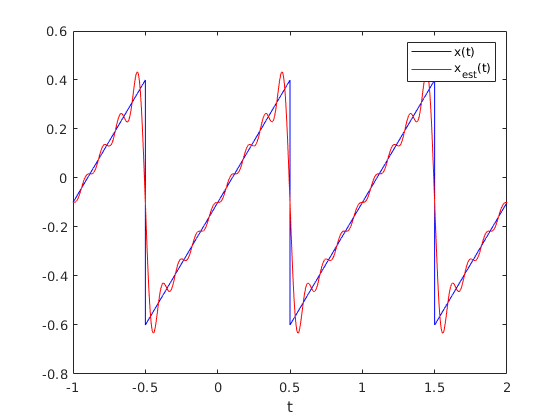

figure(fig1);
shg;
figure(fig2);
shg;

figure;
% Plot the results
plot(t, x, 'b', t, x_est, 'r')
xlabel('t');
legend('x(t)', 'x_{est}(t)');

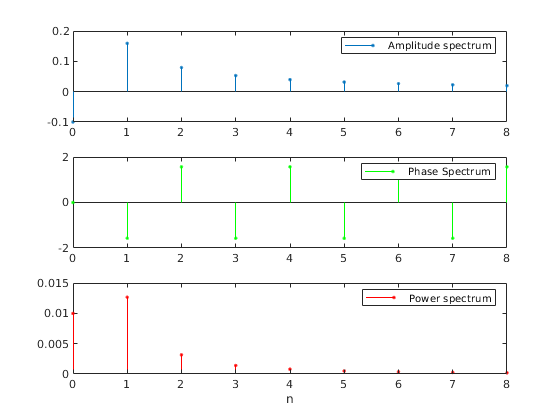


% Plot amplitude, phase and power spectrum
n0 = 0:N;

figure;
subplot(3,1,1);
stem(n0, [a0, Ak], '.');
legend ("Amplitude spectrum");

subplot(3,1,2);
stem(n0, [ksi0 ksi], '.g');
legend('Phase Spectrum');

% Plot the power spectrum (contribution) of each of the coefficients
% obtained
subplot(3,1,3);
stem(n0, [a0^2, (Ak.^2)/2], '.r');
xlabel('n');
legend('Power spectrum');

Fourier coefficient estimation function

function ak = fsAnalysis(x, t, T0, Ts, N)
% Estimates the first N coefficients of the Fourier series, for the given
% input signal, x
% T0 - fundamental period of x; 
% Ts - sampling period

% extract one period from X
% Takes one period from the linspace passed as argument
t = t(1:floor(T0/Ts));
% Takes an equal number of samples of the input signal, x
x = x(1:length(t));

w0 = 2*pi/T0;
ak = [];
for k = -N:N
    ak = [ak, (1/T0)*trapz(t, x.*exp(-j*k*w0*t))];
end

end